# Atomically resolve a metabolic reconstruction

## Author: German Preciat, Analytical BioSciences, Leiden University

## INTRODUCTION

Genome-scale metabolic network reconstructions have become a relevant tool in modern biology to study the metabolic pathways of biological systems *in silico*. However, a more detailed representation at the underlying level of atom mappings opens the possibility for a broader range of biological, biomedical and biotechnological applications than with stoichiometry alone.

This tutorial will demonstrate how to use the chimoinformatic tools in the COBRA Toolbox. The tutorial is divided into three sections: first, the chimoinformatic data of the metabolites in a COBRA model is processed generating metabolite structures in various chemoinfomatic formats; second, the atoms of their reactions are mapped; and finally, all of the tools demonstrated are used to generate a standardized chemoinformatic database specific to the COBRA model. The chemoinformatic database will be generated using information from the ecoliCore model.

## MATERIALS

#### Open Babel

To convert molecular structures, open babel must be installed. To install it, follow the steps below.

On Windows, download the [OpenBabel](https://github.com/openbabel/openbabel/releases/download/openbabel-3-1-1/OpenBabel-3.1.1.exe) installation and follow the instructions.

On *macOS*, run the following command in the Terminal:

`$ brew install open-babel`

#### CXCALC

The CXCALC tools are used to adjust the pH and create images of the metabolic structures. To install CXCALC download [MarvinSuite](https://chemaxon.com/products/marvin/download) and follow the instructions.

#### JAVA

To atom map reactions it is required to have Java version 8. Follow the instruction in [https://www.openlogic.com/openjdk-downloads](https://www.openlogic.com/openjdk-downloads). 

On *macOS*, please make sure that you run the following commands in the Terminal before continuing with this tutorial:

`$ /usr/bin/ruby -e "$(curl -fsSL` [`https://raw.githubusercontent.com/Homebrew/install/master/install`](https://raw.githubusercontent.com/Homebrew/install/master/install)`)"`

`$ brew install coreutils`

#### `PATH`

`On ``Linux`, please make sure that Java, OpenBabel and CXCALC directories are included. To do this, run the following commands:

`$ export PATH=$PATH:/usr/local/bin` (default location of OpenBabel)

`$ export PATH=$PATH:/opt/opt/chemaxon/jchemsuite/bin/` (default location of CXCALC)

`$ export PATH=$PATH:/usr/java/jre1.8.0_131/bin/` (default installation of Java)

`On Windows`:

`$ set path=%path%;C:\Program Files (x86)\OpenBabel-3.1.1` (default location of OpenBabel)

`$ set path=%path%;C:\Program Files\ChemAxon\MarvinSuite\bin` (default location of CXCALC)

Also, in order to standardise the chemical reaction format, it is required to have CXCALC with its respective license.

## Metabolites

Metabolite structures are represented in a variety of chemoinformatic formats, including 1) Metabolite chemical tables (MDL MOL) that list all of the atoms in a molecule, as well as their coordinates and bonds${\;}^1$; 2) The simplified molecular-input line-entry system (SMILES), which uses a string of ASCII characters to describe the structure of a molecule${\;}^2$; or 3) The International Chemical Identifier (InChI) developed by the IUPAC, provides a standard representation for encoding molecular structures using multiple layers to describe a metabolite structure${\;}^3$ (see Figure 1). Additionally, different chemical databases assing a particular identifier to represent the metabolite structures as the Virtual Metabolic Human database (**VMH**)${\;}^4$, the Human Metabolome Database (**HMDB**)${\;}^5$, **PubChem** database${\;}^6$, the Kyoto Encyclopedia of Genes and Genomes(**KEEG**)${\;}^7$, and the Chemical Entities of Biological Interest (**ChEBI**)${\;}^8$. 

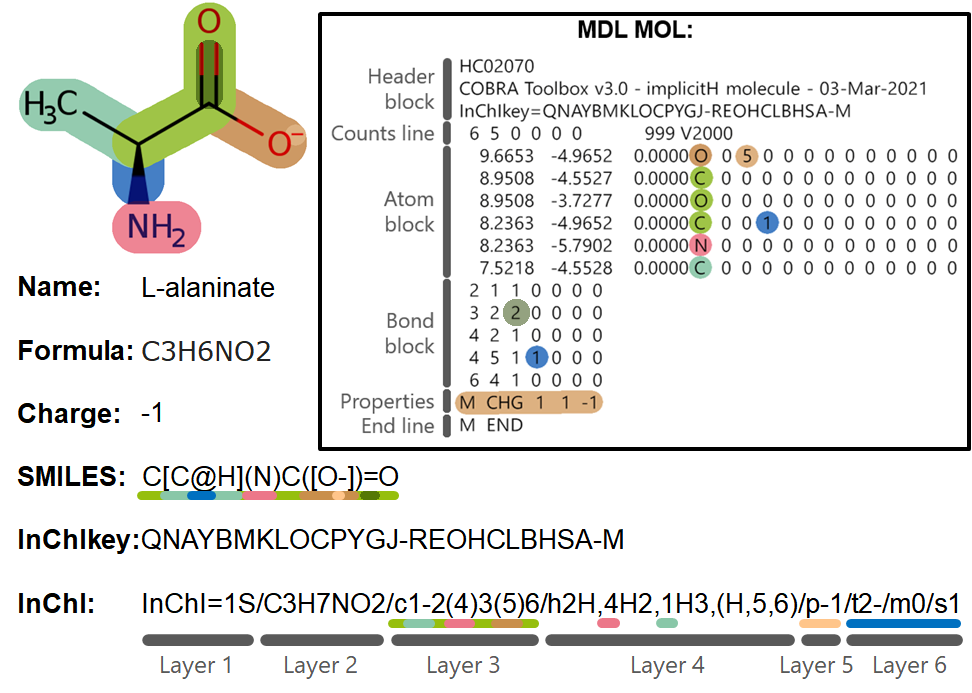

Figure 1. L-alaninate molecule represented by a hydrogen-suppressed molecular graph (implicit hydrogens). The main branch of the molecule can be seen in green; the additional branches can be seen in brown, pink and turquoise. The stereochemistry of the molecule is highlighted in blue, the double bond with dark green and the charges are highlighted in light brown. The same colours are used to indicate where this information is represented in the different chemoinformatic formats. The InChI is divided into layers, each of which begins with a lowercase letter, except for Layers 1 and 2. Layer 1 indicates if the InChI is standardised, Layer 2 the chemical formula in a neutral state, Layer 3 the connectivity between the atoms (ignoring hydrogen atoms), Layer 4 the connectivity of hydrogen atoms, Layer 5 the charge of the molecule and Layer 6 the stereochemistry. Additional layers can be added, but they cannot be represented with a standard InChI.

First we clean the workspace and define the model that will be used for conserved moiety decomposition.

clear
%modelName = 'ecoli';
modelName = 'DAS';

Setup the paths and load the model.

projectDir = strrep(which('tutorial_atomicallyResolveReconstruction'),'/tutorial_atomicallyResolveReconstruction.mlx','');
resultsDir = [projectDir filesep 'results' filesep modelName '_chemoinformatics' filesep];
switch modelName
    case 'DAS'
        tutorialdir = fileparts(which('tutorial_atomicallyResolveReconstruction.mlx'));
        model = readCbModel([tutorialdir filesep 'data' filesep 'subDas.mat']); 
    case 'ecoli'
        load ecoli_core_model.mat
        model.mets = regexprep(model.mets, '\-', '\_');
end

Check Open Babel and CXCALC installation

[oBabelInstalled, ~] = system('obabel');
if oBabelInstalled == 127
    oBabelInstalled = 0;
end
[cxcalcInstalled, ~] = system('cxcalc');
cxcalcInstalled = ~cxcalcInstalled;

### Add metabolite information

The `addMetInfoInCBmodel` function will be used to add the identifiers. The chemoinformatic data is obtained from an external file and is added to the ecoliCore model. The chemoinformatic information includes SMILES, InChIs, or different database identifiers.

dataFile = which('tutorial_atomicallyResolveReconstruction.mlx');
inputData = regexprep(dataFile, 'tutorial_atomicallyResolveReconstruction.mlx', 'metaboliteIds.txt');
expectedResults = regexprep(dataFile, 'tutorial_atomicallyResolveReconstruction.mlx', 'expectedResults');
replace = false;
[model, hasEffect] = addMetInfoInCBmodel(model, inputData, replace);

### Download metabolites from model identifiers

The `obtainMetStructures` function is used to obtain MDL MOL files from different databases, including HMDB${\;}^5$, PubChem${\;}^6$, KEEG${\;}^7$ and ChEBI${\;}^8$. Alternatively, the function can be used to convert the InChI strings or SMILES in the model to MDL MOL files. A COBRA model with identifiers is required to run the function.

The optional variables are:

The variable |mets| contains a list of metabolites to be download (Default: All). To obtain the metabolite structure of glucose, we use the VMH id.

switch modelName
    case 'DAS'
        mets = {'34dhphe'; 'dopa'; 'co2'};
    case 'ecoli'
        mets = {'2pg'; 'h2o'; 'pep'; 'fdp'; 'f6p'; 'pi'};
end

`outputDir`: Path to the directory that will contain the MOL files (default: current directory).

outputDir = resultsDir;

`sources`, is an array indicating the source of preference (default: all the sources with ID)

- InChI (requires openBabel)

- Smiles (requires openBabel)

- KEGG ([https://www.genome.jp/](https://www.genome.jp/))

- HMDB ([https://hmdb.ca/](https://hmdb.ca/))

- PubChem ([https://pubchem.ncbi.nlm.nih.gov/](https://pubchem.ncbi.nlm.nih.gov/))

- CHEBI ([https://www.ebi.ac.uk/](https://www.ebi.ac.uk/))

- DrugBank ([https://go.drugbank.com/](https://go.drugbank.com/))

- LipidMass ([https://www.lipidmaps.org/](https://www.lipidmaps.org/))

sources = {'inchi'; 'smiles'; 'kegg'; 'hmdb'; 'pubchem'; 'chebi'};

Run the function

if oBabelInstalled
    molCollectionReport = obtainMetStructures(model, mets, outputDir, sources);
else
    load([expectedResults filesep 'molCollectionReport.mat'])
end
disp(molCollectionReport.databaseCoverage)

      sources      coverage    metsWithStructure    metsWithoutStructure
    ___________    ________    _________________    ____________________

    {'chebi'  }      100               3                     0          
    {'hmdb'   }      100               3                     0          
    {'inchi'  }      100               3                     0          
    {'kegg'   }      100               3                     0          
    {'pubchem'}      100               3                     0          
    {'smiles' }      100               3                     0          



### Convert metabolites

Open Babel${\;}^9$ is a chemical toolbox designed to translate the different chemical data languages. It is possible to convert between chemical formats such as MDL MOL files to InChI. This function `openBabelConverter` converts chemoformatic formats using OpenBabel. It requires having OpenBabel installed. 

The function requires the original chemoinformatic structure (`origFormat`) and the output format (`outputFormat`). The formats supported are SMILES, MD MOL, InChI, InChIKey, rxn and rinchi. Furthermore, if the optional variable `saveFileDir` is set, the new format will be saved with the name specified in the variable.

All of the downloaded metabolite structures are converted to an InChI as follows.

switch modelName
    case 'DAS'
        met = 'dopa';
    case 'ecoli'
        met = 'f6p';
end
if oBabelInstalled
    [inchis, smiles] = deal(cell(size(mets)));
    for i = 1:length(sources)
        metaboliteDir = [outputDir 'metabolites' filesep sources{i} filesep];
        if isfile([metaboliteDir met '.mol'])
            inchis{i, 1} = openBabelConverter([metaboliteDir met '.mol'], 'inchi');
            smiles{i, 1} = openBabelConverter(inchis{i, 1}, 'smiles');
        end
    end
else
    load([expectedResults filesep 'inchisSmiles.mat'])
end
table(sources, inchis, smiles)

ans = 6×3 table
      sources                                        inchis                                                smiles          
    ___________    __________________________________________________________________________    __________________________

    {'inchi'  }    {'InChI=1S/C8H11NO2/c9-4-3-6-1-2-7(10)8(11)5-6/h1-2,5,10-11H,3-4,9H2/p+1'}    {'c1cc(c(cc1CC[NH3+])O)O'}
    {'smiles' }    {'InChI=1S/C8H11NO2/c9-4-3-6-1-2-7(10)8(11)5-6/h1-2,5,10-11H,3-4,9H2/p+1'}    {'c1cc(c(cc1CC[NH3+])O)O'}
    {'kegg'   }    {'InChI=1S/C8H11NO2/c9-4-3-6-1-2-7(10)8(11)5-6/h1-2,5,10-11H,3-4,9H2'    }    {'c1cc(c(cc1CCN)O)O'     }
    {'hmdb'   }    {'InChI=1S/C8H11NO2/c9-4-3-6-1-2-7(10)8(11)5-6/h1-2,5,10-11H,3-4,9H2'    }    {'c1cc(c(cc1CCN)O)O'     }
    {'pubchem'}    {'InChI=1S/C8H11NO2/c9-4-3-6-1-2-7(10)8(11)5-6/h1-2,5,10-11H,3-4,9H2'    }    {'c1cc(c(cc1CCN)O)O'     }
    {'chebi' 

### InChI comparison

With the function `compareInchis`, each InChI string is given a score based on its similarity to the chemical formula and charge of the metabolite in the model. Factors such as stereochemistry, if it is a standard inchi, and its similarity to the other inchis are also considered. The InChI with the highest score is the identifier considered as more consistent with the model.

comparisonTable = compareInchis(model, inchis, met);
display(comparisonTable)

comparisonTable = 6×15 table
    scores    rGroup                                      InChI                                       metFormula    formulaOkBool    netCharge    chargeOkBool    stereochemicalSubLayers    standard    sourceSimilarity    mainLayerSimilarity    isotopicLayer    layers    inchiWithMoreLayers                                 mainLayer                              
    ______    ______    __________________________________________________________________________    __________    _____________    _________    ____________    _______________________    ________   

### Metabolite structure standardisation

Standardize an MDL MOL file directory by representing the reaction using normal chemical graphs, hydrogen suppressed chemical graphs, and chemical graphs with protonated molecules. The function also updates the header with the standardization information. It makes use of CXCALC and OpenBabel.

Standardisation

- explicitH: Chemical graphs; 

- implicitH: Hydrogen suppressed chemical graph; 

- basic: Update the header. 

switch modelName
    case 'DAS'
        standardisationApproach = 'implicitH';
    case 'ecoli'
        standardisationApproach = 'explicitH';
end
if oBabelInstalled
    inchiDir = [outputDir 'metabolites' filesep 'inchi' filesep];
    metList = mets;
    standardisedDir = [outputDir 'mets' filesep];
    standardisationReport = standardiseMolDatabase(inchiDir, metList, ...
        standardisedDir, standardisationApproach);
else
    standardisedDir =[expectedResults filesep modelName '_chemoinformatics' filesep 'mets' filesep];
end


 Standardizing 3 MOL files ... 


### Metabolite structures

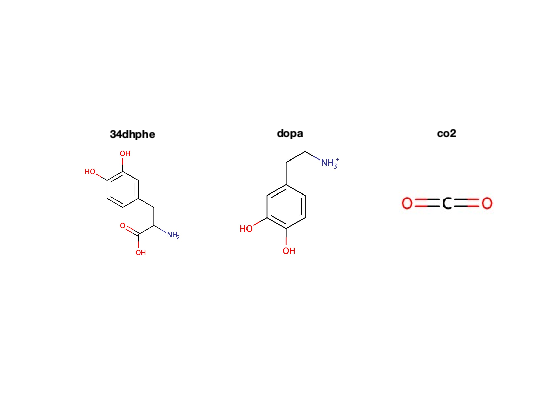

if cxcalcInstalled
    imagesFolder = [standardisedDir 'images' filesep];
else
    imagesFolder = [expectedResults filesep modelName '_chemoinformatics' filesep 'mets' filesep 'images' filesep];
end
figure
for i = 1:length(mets)
    subplot(numel(mets)/3, 3, i)
    imshow([imagesFolder mets{i} '.jpeg'])
    title(mets{i})
end

clearvars -except model resultsDir modelName standardisedDir standardisationApproach oBabelInstalled cxcalcInstalled expectedResults

## Reactions

A set of atom mappings represents the mechanism of each chemical reaction in a metabolic network, each of which relates an atom in a substrate metabolite to an atom of the same element in a product metabolite (Figure 1). To atom map reactions in a metabolic network reconstruction, one requires chemical structures in a data file format (SMILES, MDL MOL, InChIs), reaction stoichiometries, and an atom mapping algorithm.

A set of atom mappings represents the mechanism of each chemical reaction in a metabolic network, each of which relates an atom in a substrate metabolite to an atom of the same element in a product metabolite (Figure 1). To atom map reactions in a metabolic network reconstruction, one requires chemical structures in a data file format (SMILES, MDL MOL and InChIs), reaction stoichiometries, and an atom mapping algorithm.

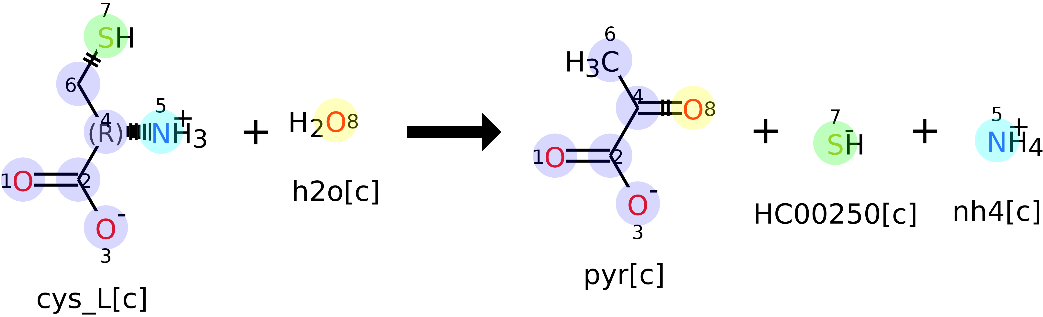

Figure 1. Set of atom mappings for reaction L-Cysteine L-Homocysteine-Lyase (VMH ID: r0193).

Metabolite structures and reaction stoichiometries from the genome-scale reconstruction are used to generate reaction chemical tables containing information about the chemical reactions (MDL RXN). The metabolic reactions are atom mapped using the Reaction Decoder Tool (RDT) algorithm${\;}^{11}$, which was chosen after comparing the performance of published atom mapping algorithms${\;}^{12}$. Atom map metabolic reactions Atom mappings for the internal reactions of a metabolic network reconstruction are performed by the function `obtainAtomMappingsRDT`. 

For this section, the atom mappings are generated based on the molecular structures obtained and the ecoli core model. 

The function `obtainAtomMappingsRDT` generates 4 different directories containing: 

- the atom mapped reactions in MDL RXN format (directory *atomMapped*), 

- the images of the atom mapped reactions (directory *images*), 

- additional data for the atom mapped reactions (SMILES, and product and reactant indexes) (directory *txtData*), and 

- the unmapped MDL RXN files (directory *rxnFiles*). 

The input variable `outputDir` indicates the directory where the folders will be generated (by default the function assigns the current directory).

## Atom map a reaction

The main inputs of the `obtainAtomMappingsRDT function `are a COBRA model structure and a directory containing the molecular structures in MDL MOL format. The variable `molFileDir `contains the path to the directory containing MOL files of the COBRA model. 

molFileDir = [standardisedDir 'molFiles' filesep];

The variable `rxnDir` specifies the path to the directory containing the RXN files with atom mappings.

rxnDir = [resultsDir 'rxns'];

The input variable `rxnsToAM` indicates the reactions that will be atom mapped. By default the function atom map all the internal reactions with all of its metabolites present in the metabolite database (`molFileDir`).

switch modelName
    case 'DAS'
        rxnsToAM = {'R3'};
    case 'ecoli'
        rxnsToAM = {'ENO'; 'FBP'};
end

The variable `hMapping`, indicates if the hydrogen atoms will be also atom mapped (Default: `true`).

hMapping = true;

Finally, the variable `onlyUnmapped` indicates if only the reaction files will be generated without atom mappings (Default: `false`).

onlyUnmapped = false;

Now, let's obtain the atom map using `obtainAtomMappingsRDT`: 

if oBabelInstalled
    atomMappingReport = obtainAtomMappingsRDT(model, molFileDir, rxnDir, rxnsToAM, hMapping, onlyUnmapped);
    imagesFolder = [rxnDir filesep 'images' filesep];
    atomMapDir = [rxnDir filesep 'atomMapped'];
else
    imagesFolder = [expectedResults filesep modelName '_chemoinformatics' filesep 'rxns' filesep 'images' filesep];
    atomMapDir = [expectedResults filesep modelName '_chemoinformatics' filesep 'rxns' filesep 'atomMapped'];
end



Generating RXN files.
Computing atom mappings for 1 reactions.



The output, `atomMappingReport,` contains a report of the reactions written which include:

- `rxnFilesWritten`: The MDL RXN written.

- `balanced`: The atomically balanced reactions.

- `unbalanced`: The atomically unbalanced reactions.

- mapped: The atom mapped reactions.

- `notMapped:` The unmapped reactions.

- `inconsistentBool`: A Boolean vector indicating the inconsistent reactions.

- `rinchi`: The reaction InChI for the MDL RXN files written.

- `rsmi`: The reaction SMILES for the MDL RXN files written.

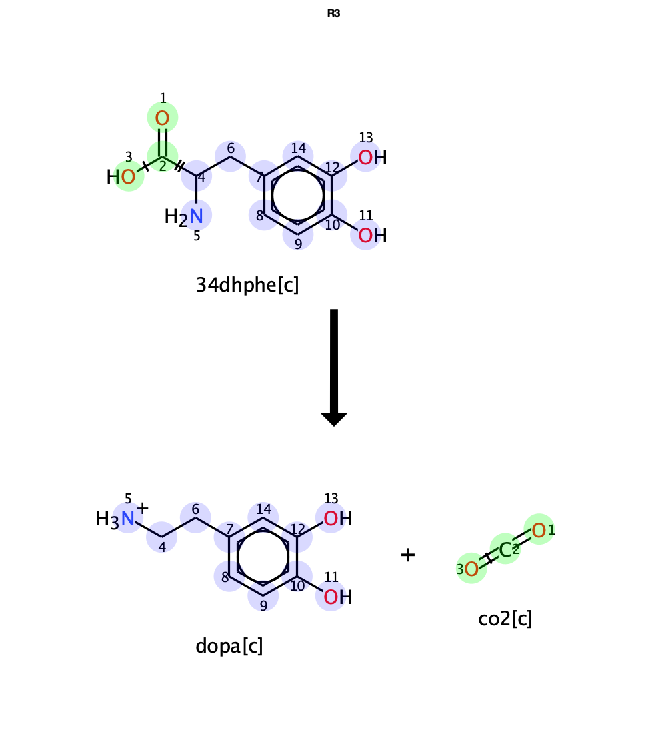

figure
for i = 1:length(rxnsToAM)
    subplot(1, 1/numel(rxnsToAM), i)
    imshow([imagesFolder rxnsToAM{i} '.png'])
    title(rxnsToAM{i})
end

### Read atom mapping data

The information of an atom mapped reaction is extracted using the function `readAtomMappingFromRxnFile`, which includes a metabolite identifier, the element, the atom mapping index, the identification of substrate or product, and a vector indicating which instance of a repeated metabolite atom I belongs to. The atom mapped data for the reaction enolase is extracted in the following example.

[mets, elements, metNrs, rxnNrs, isSubstrate, instances] = readAtomMappingFromRxnFile(rxnsToAM{1}, atomMapDir);
display(table(mets, elements, metNrs, rxnNrs, isSubstrate, instances))

  28×6 table

         mets         elements    metNrs    rxnNrs    isSubstrate    instances
    ______________    ________    ______    ______    ___________    _________

    {'34dhphe[c]'}     {'N'}         1         1         true            1    
    {'34dhphe[c]'}     {'C'}         2         2         true            1    
    {'34dhphe[c]'}     {'C'}         3         3         true            1    
    {'34dhphe[c]'}     {'C'}         4         4         true            1    
    {'34dhphe[c]'}     {'C'}         5         5         true            1    
    {'34dhphe[c]'}     {'C'}         6         6         true            1    
    {'34dhphe[c]'}     {'O'}         7         7         true            1    
    {'34

### Find the enthalpy change and number of bonds broken and formed

The `findEnthalpyChange` and `findBondsBrokenAndFormed` functions are used to calculate the enthalpy change or the number of broken and formed bonds of each reaction in list `rxnsToAM` using the reaction mechanism identified by the atom mapping. Furthermore, the total weight of all substrates is calculated by adding the atomic weight of each atom.

[enthalpyChange, substrateMass] = findEnthalpyChange(model, rxnsToAM, atomMapDir);
[bondsBrokenAndFormed, ~] = findBondsBrokenAndFormed(model, rxnsToAM, atomMapDir);

Make a table of enthalpy change, bonds broken and formed, and sort it by modified bonds.

rxnDataTable = table(rxnsToAM, bondsBrokenAndFormed, enthalpyChange, substrateMass, ...
    'VariableNames', {'rxns','bondsBrokenAndFormed', 'enthalpyChange', 'substrateMass'});
rxnDataTable = sortrows(rxnDataTable, {'bondsBrokenAndFormed'}, {'descend'});
display(rxnDataTable)

rxnDataTable = 1×4 table
     rxns     bondsBrokenAndFormed    enthalpyChange    substrateMass
    ______    ____________________    ______________    _____________

    {'R3'}             2                   -95              186.1    


clearvars -except model resultsDir modelName standardisedDir standardisationApproach oBabelInstalled cxcalcInstalled expectedResults

## Chemoinformatic database

The function `generateChemicalDatabase` generates a chemoinformatic database of standardised metabolite structures and atom-mapped reactions on a genome-scale metabolic reconstruction using the tools described in this tutorial. In order to identify the metabolite structure that most closely resembles the metabolite in the genome-scale reconstruction, identifiers from different sources are compared based on their InChI (See Table 1). Finally, the obtained atom mapped reactions are used to identify the number of broken and formed bonds, as well as the enthalpy change of the reactions in the genome-scale reconstruction.

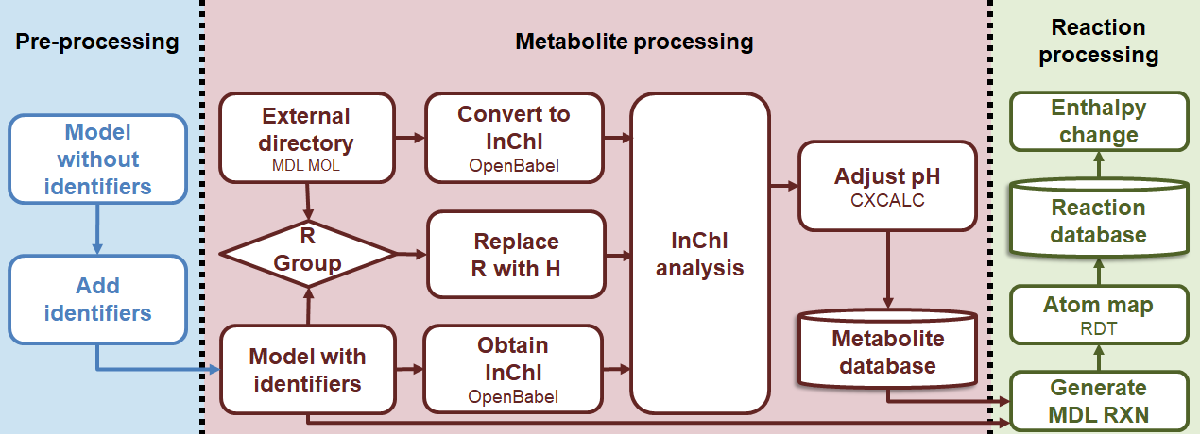

Figure 2. `generateChemicalDatabase` workflow

Table 1. InChI scoring criteria.

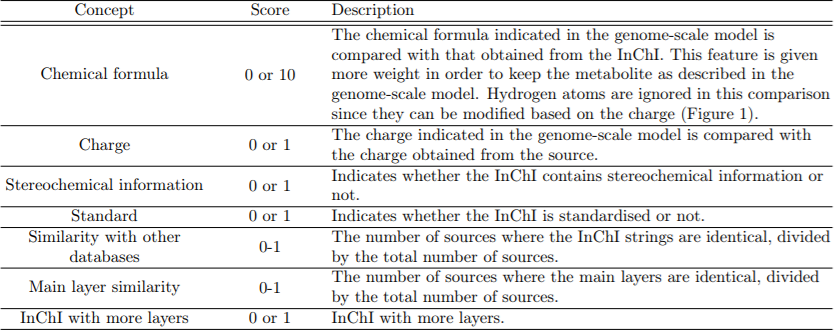

The goal of the comparison is to obtain a larger number of atomically balanced metabolic reactions. The Reaction Decoder Tool algorithm${\;}^8$ (**RDT**) is used to obtain the atom mappings of each metabolic reaction. The atom mapping data is used to calculate the number of bonds formed or broken in a metabolic reaction, as well as the enthalpy change. The information gathered is incorporated into the COBRA model.

We will obtain chemoinformatic database of the Ecoli core model in this tutorial. 

The user-defined parameters in the function `generateChemicalDatabase` will activate various processes. Each parameter is contained in the struct array  `options` and described in detail below:

- **outputDir**: The path to the directory containing the chemoinformatic database (default: current directory)

- **printlevel**: Verbose level 

- **standardisationApproach**: String containing the type of standardisation for the molecules (default: 'explicitH' if openBabel${\;}^9$ is installed, otherwise default: 'basic'):

- explicitH: Chemical graphs; 

- implicitH: Hydrogen suppressed chemical graph; 

- basic: Update the header. 

- **keepMolComparison**: Logical value, indicate if all metabolite structures per source will be saved or not.

- **onlyUnmapped**: Logic value to select create only unmapped MDL RXN files (default: FALSE, requires Java to run the RDT${\;}^{11}$). 

- **adjustToModelpH**: Logic value used to determine whether a molecule's pH must be adjusted in accordance with the COBRA model. (default: TRUE, requires MarvinSuite${\;}^{10}$). 

- **addDirsToCompare**: Cell(s) with the path to directory to an existing database (default: empty).

- **dirNames**: Cell(s) with the name of the directory(ies) (default: empty).

- **debug**: Logical value used to determine whether or not the results of different points in the function will be saved for debugging (default: empty).

options.outputDir = [resultsDir 'database'];
options.printlevel = 1;
options.debug = true;
options.standardisationApproach = standardisationApproach;
options.adjustToModelpH = true;
options.keepMolComparison = false;
options.onlyUnmapped = false;

Use the function `generateChemicalDatabase`

--------------------------------------------------------------
CHEMICAL DATABASE
--------------------------------------------------------------
 
Generating a chemical database with the following options:
 
                  outputDir: '/Users/gpreciat/work/code/COBRA.tutorials/analysis/atomicallyResolveReconstruction/results/DAS_chemoinformatics/database'
                 printlevel: 1
                      debug: 1
    standardisationApproach: 'implicitH'
            adjustToModelpH: 1
          keepMolComparison: 0
               onlyUnmapped: 0

--------------------------------------------------------------
Obtaining MOL files from chemical databases ...

  8×4 table

       sources       coverage    metsWithStructure    metsWithoutStructure
    _____________    ________    _________________    _

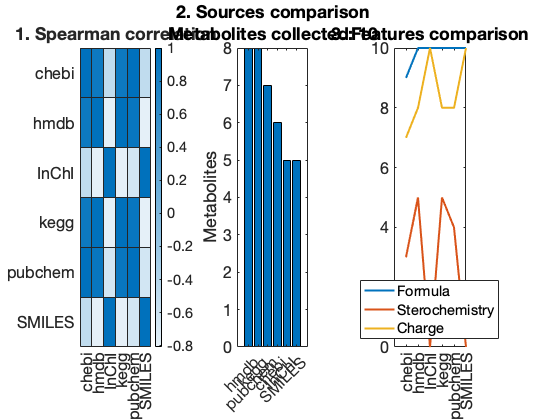

Adjusting pH based on the model's chemical formula ...
 
adjustedpH:
  10×11 table

       mets                         source                     score                                                                   inchi                                                                   chargeOkBool    metFormula     needAdjustmentBool    notPossible2AdjustBool    differentFormula    loopError    pHRangePassed
    ___________    ________________________________________    ______    __________________________________________________________________________________________________________________________________    ____________    ___________

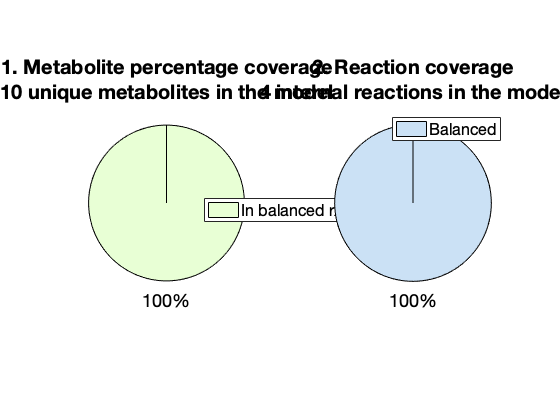

Calculating bonds broken and formed and enthalpy change...
No model.biomassRxnAbbr? Give abbreviation of biomass reaction if there is one.
Exchanges that would otherwise have been missed without abbreviation prefix search:
Coefficient	Metabolite	#		Reaction		#
-1			phe_L[c]	1	E1		5
-1			o2[c]		3	E2		6
-1			h2o[c]		6	E3		7
-1			dopa[c]		8	E4		8
-1			co2[c]		9	E5		9
-1			for[c]		10	E6		10


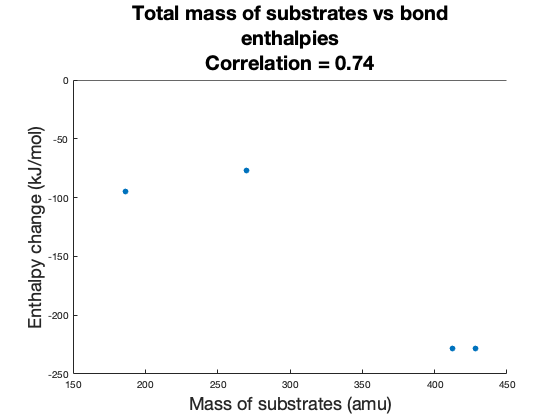

No model.biomassRxnAbbr? Give abbreviation of biomass reaction if there is one.
Exchanges that would otherwise have been missed without abbreviation prefix search:
Coefficient	Metabolite	#		Reaction		#
-1			phe_L[c]	1	E1		5
-1			o2[c]		3	E2		6
-1			h2o[c]		6	E3		7
-1			dopa[c]		8	E4		8
-1			co2[c]		9	E5		9
-1			for[c]		10	E6		10


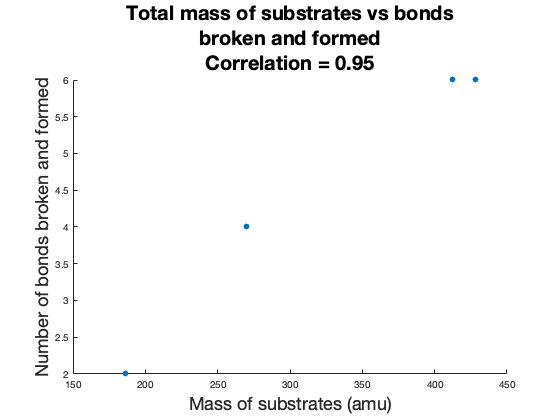

  4×5 table

     rxns     rxnNames    bondsBrokenAndFormed    enthalpyChange    substrateMass
    ______    ________    ____________________    ______________    _____________

    {'R1'}     {'R1'}            {'6'}               {'-228'}          412.23    
    {'R2'}     {'R2'}            {'6'}               {'-228'}          428.23    
    {'R4'}     {'R4'}            {'4'}               {' -77'}          270.14    
    {'R3'}     {'R3'}            {'2'}               {' -95'}           186.1    

Diary written to: /Users/gpreciat/work/code/COBRA.tutorials/analysis/atomicallyResolveReconstruction/results/DAS_chemoinformatics/database
generateChemicalDatabase run is complete.


if oBabelInstalled && cxcalcInstalled
    info = generateChemicalDatabase(model, options);
    metDir = [options.outputDir filesep 'mets' filesep 'molFiles'];
else
    load([expectedResults filesep modelName '_chemoinformatics' filesep 'database' filesep '7.debug_endOfGenerateChemicalDatabase.mat']);
    metDir = [expectedResults filesep modelName '_chemoinformatics' filesep 'database' filesep 'mets' filesep 'molFiles'];
end

Finally, the function `metDatabaseStatus` is used to check the  consistency of the metabolites in a database in relation to a COBRA model, as well as, showing the type of identifiers in the model.

[summary, status] = metDatabaseStatus(model, metDir)

summary = struct with fields:
                            mets: 10
                      consistent: 2
             inconsistentFormula: 0
              inconsistentCharge: 8
    inconsistentChargeAndFormula: 0
                         missing: 0
                        inchiIds: 10
                       smilesIds: 10
                        chebiIds: 9
                         hmdbIds: 10
                         keggIds: 10
                      pubchemIds: 10


status = 10×13 table
       met              status           noOfIds    modelFormula    structureFormula    modelCharge    structureCharge    inchiBool    smilesBool    chebiBool    hmdbBool    pubchemBool    keggBool
    _________    ____________________    _______    ____________    ________________    ___________    _______________    _________    __________    _________    ________    ___________    ________

    "34dhphe"    "inconsistentCharge"       6       "C9H11NO4"          "C9NO4"              0                0             true         tru

## Bibliography

- Dalby et al., "Description of several chemical structure file formats used by computer programs developed at molecular design limited", **(2002).**

- Anderson et al., "Smiles: A line notation and computerized interpreter for chemical structures", *Environmental research Brief* **(1987)**.

- Helle et al., "Inchi, the iupac international chemical identifier", *Journal of Cheminformatics* **(2015)**.

- Noronha et al., "The Virtual Metabolic Human database: integrating human and gut microbiome metabolism with nutrition and disease", *Nucleic acids research*  **(2018).**

- Wishart et al., "HMDB 4.0 — The Human Metabolome Database for 2018_"._ *Nucleic acids research* **(2018).**

- Sunghwan et al. “PubChem in 2021: new data content and improved web interfaces.”  *Nucleic acids research* **(2021).**

- Kanehisa, and Goto. "KEGG: Kyoto Encyclopedia of Genes and Genomes". *Nucleic acids research* **(2000).**

- Hastings et al,. "ChEBI in 2016: Improved services and an expanding collection of metabolites". *Nucleic acids research* **(2016).**

- O'Boyle et al,. "Open Babel: An open chemical toolbox." *Journal of Cheminformatics*  **(2011).**

- "Marvin was used for drawing, displaying and characterizing chemical structures, substructures and reactions, ChemAxon ([<http://www.chemaxon.com](http://www.chemaxon.com/)>)"

- Rahman et al,. "Reaction Decoder Tool (RDT): Extracting Features from Chemical Reactions", Bioinformatics **(2016).**

- Preciat et al., "Comparative evaluation of atom mapping algorithms for balanced metabolic reactions: application to Recon3d", *Journal of Cheminformatics* **(2017)**.